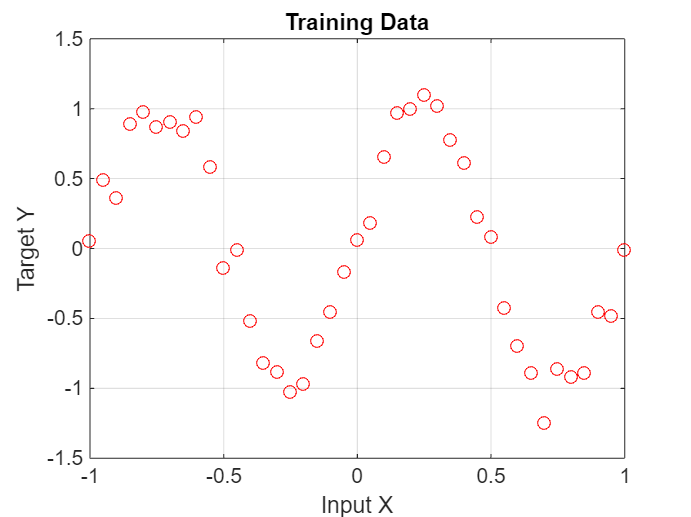

clc; clear; close all;

%% Step 1: Generate Training Data
% Define input (X) and target (Y) data
X = (-1:0.05:1)';  % Column vector with input values
Y = sin(2*pi*X) + 0.1 * randn(size(X));  % Target with small noise

% Plot the training data
figure;
plot(X, Y, 'ro');
xlabel('Input X');
ylabel('Target Y');
title('Training Data');
grid on;


%% Step 2: Define Neural Network Structure
num_inputs = 1;       % One input neuron
num_hidden = 10;      % Number of hidden neurons
num_outputs = 1;      % One output neuron

% Initialize weights and biases randomly
W1 = randn(num_hidden, num_inputs);  % Weights for hidden layer
b1 = randn(num_hidden, 1);           % Bias for hidden layer
W2 = randn(num_outputs, num_hidden); % Weights for output layer
b2 = randn(num_outputs, 1);          % Bias for output layer

%% Step 3: Define Activation Functions
ReLU = @(x) max(0, x);  % ReLU activation
ReLU_deriv = @(x) double(x > 0);  % Derivative of ReLU

%% Step 4: Training the Neural Network
learning_rate = 0.1;
epochs = 5000;  % Number of training iterations

mse_loss = zeros(epochs, 1);  % Store loss at each epoch

for epoch = 1:epochs
    % ---- Forward Pass ----
    Z1 = W1 * X' + b1;   % Linear transformation for hidden layer
    A1 = ReLU(Z1);       % Apply ReLU activation

    Z2 = W2 * A1 + b2;   % Linear transformation for output layer
    Y_pred = Z2;         % Output (linear activation)

    % ---- Compute Loss (Mean Squared Error) ----
    loss = mean((Y' - Y_pred).^2);  
    mse_loss(epoch) = loss;  % Store loss

    % ---- Backpropagation ----
    dZ2 = Y_pred - Y';  % Output layer error
    dW2 = (dZ2 * A1') / length(X);
    db2 = mean(dZ2, 2);

    dA1 = W2' * dZ2;
    dZ1 = dA1 .* ReLU_deriv(Z1);  % Using ReLU derivative
    dW1 = (dZ1 * X) / length(X);
    db1 = mean(dZ1, 2);

    % ---- Gradient Descent Update ----
    W1 = W1 - learning_rate * dW1;
    b1 = b1 - learning_rate * db1;
    W2 = W2 - learning_rate * dW2;
    b2 = b2 - learning_rate * db2;

    % Display progress
    if mod(epoch, 500) == 0
        fprintf('Epoch %d, Loss: %.6f\n', epoch, loss);
    end
end

Epoch 500, Loss: 0.198175
Epoch 1000, Loss: 0.171060
Epoch 1500, Loss: 0.156913
Epoch 2000, Loss: 0.145204
Epoch 2500, Loss: 0.179135
Epoch 3000, Loss: 0.142062
Epoch 3500, Loss: 0.247165
Epoch 4000, Loss: 0.152417
Epoch 4500, Loss: 0.182781
Epoch 5000, Loss: 0.165811


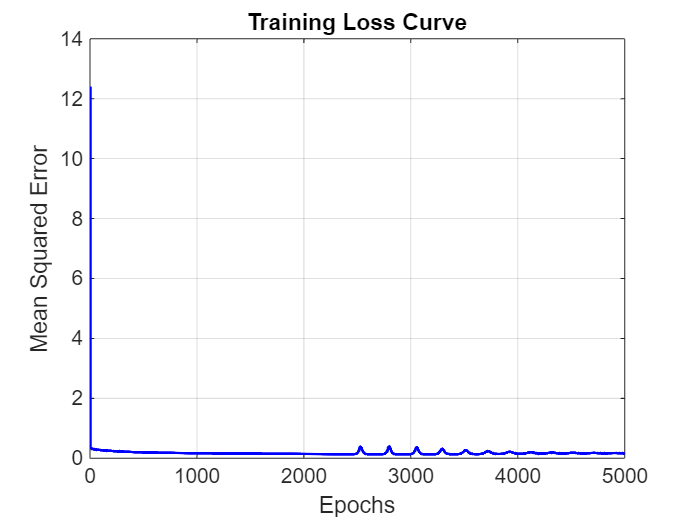


%% Step 5: Plot Training Loss
figure;
plot(1:epochs, mse_loss, 'b', 'LineWidth', 1.5);
xlabel('Epochs');
ylabel('Mean Squared Error');
title('Training Loss Curve');
grid on;

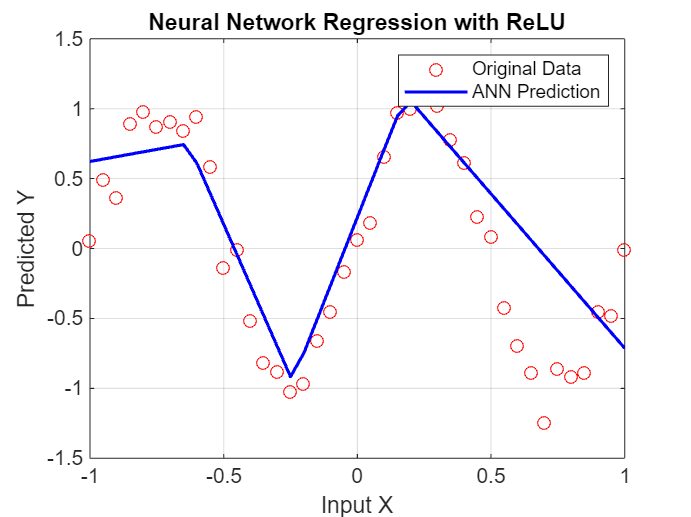


%% Step 6: Evaluate and Plot Predictions
Y_final = W2 * ReLU(W1 * X' + b1) + b2;  % Final output

figure;
plot(X, Y, 'ro', 'DisplayName', 'Original Data');
hold on;
plot(X, Y_final', 'b-', 'LineWidth', 1.5, 'DisplayName', 'ANN Prediction');
xlabel('Input X');
ylabel('Predicted Y');
title('Neural Network Regression with ReLU');
legend;
grid on;